We make an image from some text, then reload it as a matrix.

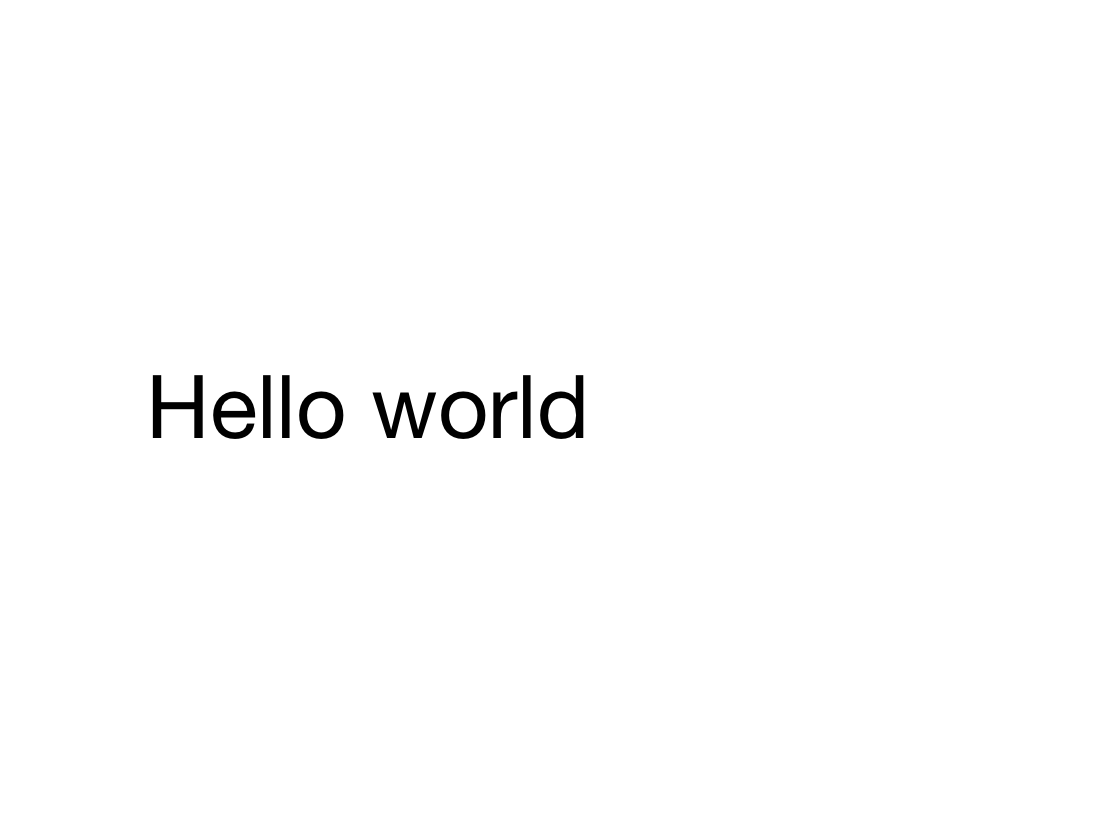

tobj = text(0,0,'Hello world','fontsize',44);
ex = get(tobj,'extent');      % ignore this line 
axis([ex(1) ex(1)+ex(3) ex(2) ex(2)+ex(4)]), axis off   % ignore this line 
saveas(gcf,'hello.png')

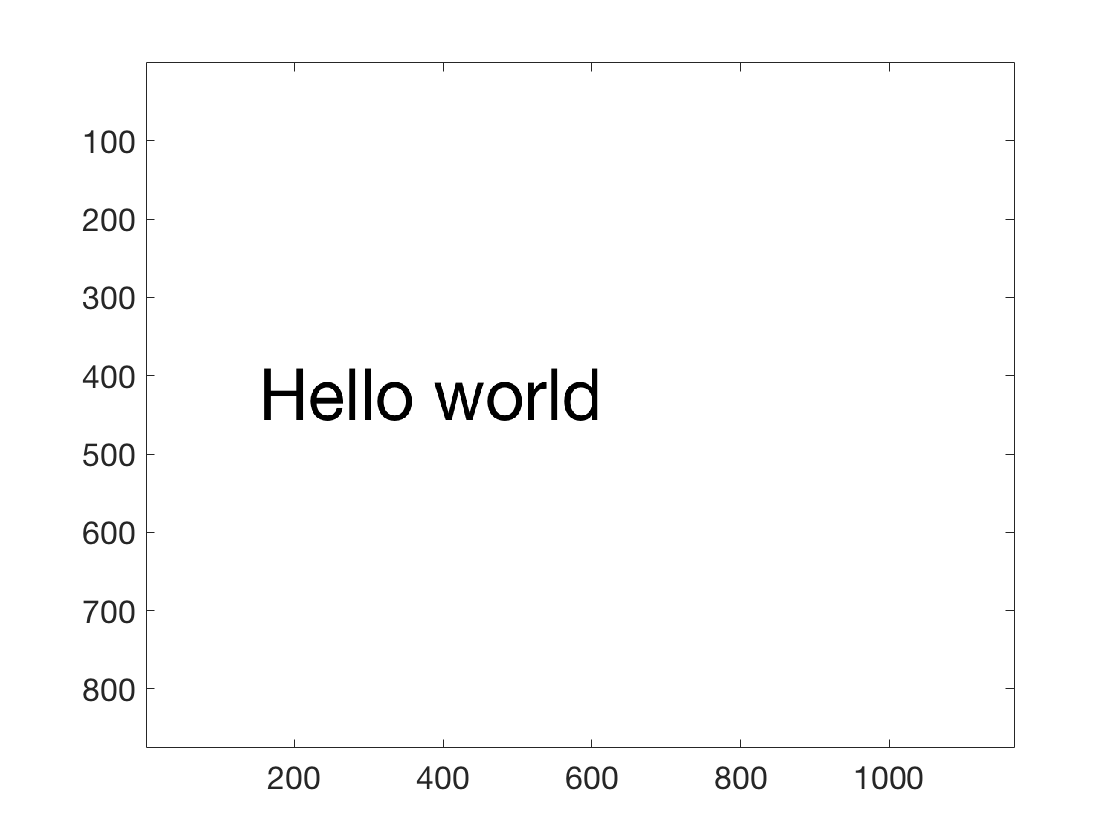

A = imread('hello.png');
A = double(rgb2gray(A));
imagesc(A),  colormap gray

[m,n] = size(A)

m =    875


n =         1167


Next we show that the singular values decrease exponentially, until they reach zero (more precisely, are about $\sigma_1 \varepsilon_{\rm mach}$). For all numerical purposes, this determines the rank of the matrix.

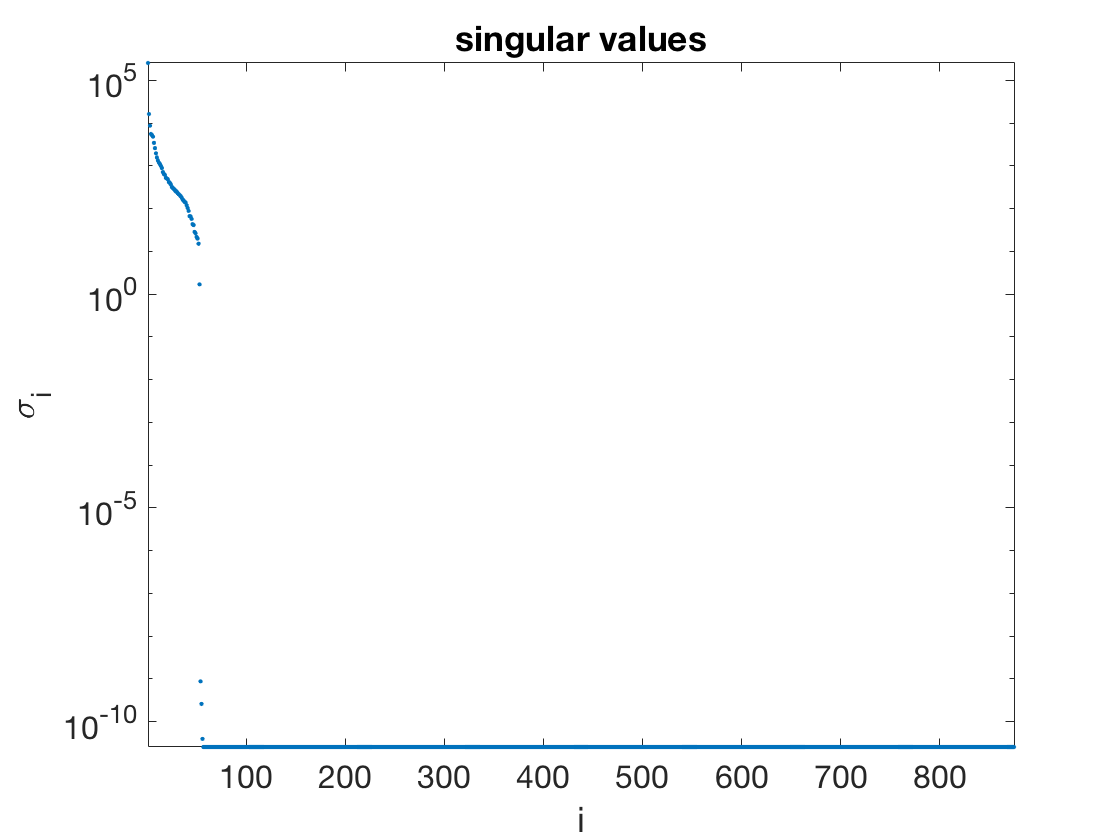

[U,S,V] = svd(A);
sigma = diag(S);
semilogy(sigma,'.')
title('singular values'), axis tight        % ignore this line 
xlabel('i'), ylabel('\sigma_i')  % ignore this line 

r = find(sigma/sigma(1) > 10*eps,1,'last')

r =     54


The rapid decrease suggests that we can get fairly good low-rank approximations. 

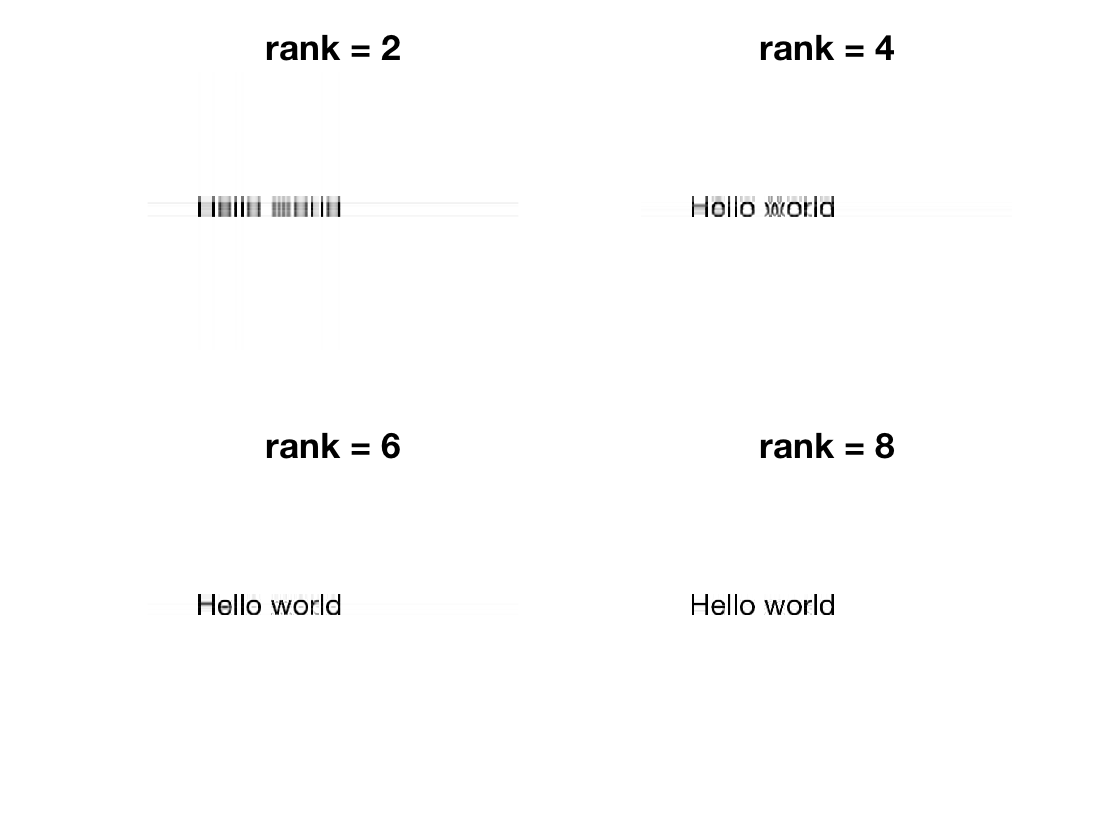

for i = 1:4
    subplot(2,2,i)
    k = 2*i;
    Ak = U(:,1:k)*S(1:k,1:k)*V(:,1:k)';
    imshow(Ak,[0 255])
    title(sprintf('rank = %d',k))
end

Consider how little data is needed to reconstruct these images. For rank 8, for instance, we have 8 left and right singular vectors plus 8 singular values, for a compression ratio of better than 25:1. 

compression = 8*(m+n+1) / (m*n)

compression =    0.016005875872200
